# One-step FAVAR

Tutorial file for testing one-step FAVAR estimators

## Housekeeping

clear
close all
clear classes

rehash path


import factorOnestep.*  



## Convenience functions

The `extremesFunc` function compresses any number of samples (draws from the posterior) into two numbers - the minimum and the maximum.

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];

medianFunc = @(x) median(x, 2);

flatFunc = @(x) x(:, :);

defaultColors = get(0, "defaultAxesColorOrder");

## Number of Samples

numPresampled = 100;

## Prepare meta information for the models

Note that the meta information is common to all one-factor FAVAR models, regardless of the specific estimator used.

The properties specific to the one-step FAVAR are as follows (on top of the base properties):

**reducibleNames** – variables used for constructing the factors. 

**numFactors** – defines how many factors to use

**Important notes: **having more blocks or using the **"slowfast"** method are not allowed for one-step estimation. Therefore only one block is created which is named automatically to **"main"**. Also since onestep method is working with standardized data, **intercept** is not allowed.

estimStart = datex.m(1960,3);
estimEnd = datex.m(2001,8);
estimSpan = datex.span(estimStart, estimEnd);

meta = Meta( ...
    endogenousNames=["FYFF"],...
    exogenous=[],...
    order=13, ...
    estimationSpan=estimSpan, ...
    reducibleNames=["IPP" , "IPF" , "IPC" , "IPCD" , "IPCN" , "IPE" , "IPI" , "IPM" , "IPMD" , "IPMND" ,...
        "IPMFG" , "IPD" , "IPN" , "IPMIN" , "IPUT" , "IP" , "IPXMCA" , "PMI" , "PMP" , "GMPYQ" , "GMYXPQ" , ...
        "LHEL" , "LHELX" , "LHEM" , "LHNAG" , "LHUR" , "LHU680" , "LHU5" , "LHU14" , "LHU15" , "LHU26" ,...
        "LPNAG" , "LP" , "LPGD" , "LPMI" , "LPCC" , "LPEM" , "LPED" , "LPEN" , "LPSP" , "LPTU" , "LPT" ,...
        "LPFR" , "LPS" , "LPGOV" , "LPHRM" , "LPMOSA" , "PMEMP" , "GMCQ" , "GMCDQ" , "GMCNQ" , "GMCSQ" ,...
        "GMCANQ" , "HSFR" , "HSNE" , "HSMW" , "HSSOU" , "HSWST" , "HSBR" , "HMOB" , "PMNV" , "PMNO" , ...
        "PMDEL" , "MOCMQ" , "MSONDQ" , "FSNCOM" , "FSPCOM" , "FSPIN" , "FSPCAP" , "FSPUT" , "FSDXP" , ...
        "FSPXE" , "EXRSW" , "EXRJAN" , "EXRUK" , "EXRCAN" , "FYGM3" , "FYGM6" , "FYGT1" , "FYGT5" , ...
        "FYGT10" , "FYAAAC" , "FYBAAC" , "SFYGM3" , "SFYGM6" , "SFYGT1" , "SFYGT5" , "SFYGT10" , ...
        "SFYAAAC" , "SFYBAAC" , "FM1" , "FM2" , "FM3" , "FM2DQ" , "FMFBA" , "FMRRA" , "FMRNBA" , ...
        "FCLNQ" , "FCLBMC" , "CCINRV" , "PMCP" , "PWFSA" , "PWFCSA" , "PWIMSA" , "PWCMSA" , "PSM99Q" , ...
        "PUNEW" , "PU83" , "PU84" , "PU85" , "PUC" , "PUCD" , "PUS" , "PUXF" , "PUXHS" , "PUXM" , "LEHCC" , "LEHM" , "HHSNTN"], ...   
    numFactors = 2, ...
    identificationHorizon=12);

## Specifying and loading input data

inputTbx = tablex.fromFile("FAVAR.csv");
dataH = DataHolder(meta, inputTbx);

## Reduced form models

The estimator-specific settings are always the same as those for the corresponding plain BVARs. Also there are some common settings for all the one-step estimations. these are

**LoadingVariance ** – prior variance for the factor loadings

**SigmaShape ** – prior on the shape parameter of the IG distribution of the covariance matrix.

**SigmaScale ** – prior on the shape parameter of the IG distribution of the covariance matrix

### Basic FAVARs

#### **Minnesota priors**

**Sigma** – controls the priors used for calculating the covariance matrix. Possible values are:

- **ar** – uses the variances matrix from estimated AR models foer each variable (with the same order as the final model),

- **diag** – uses only the diagonal elements of the covariance matrix from an estimated VAR (with the same order as the final model),

- **full** – uses the full covariance matrix from an estimated VAR (with the same order as the final model).

estimatorR1 = estimator.MinnesotaFAVAROnestep()

estimatorR1 =   MinnesotaFAVAROnestep with properties:

                Settings: [1×1 factorOnestep.estimator.settings.MinnesotaFAVAROnestep]
             Description: "One-step FAVAR with Minnesota prior"
                Category: "One-step plain FAVAR estimators"
           HasCrossUnits: 0
         CanBeIdentified: 1
          OneStepFactors: 1
                   FAVAR: []
          CanHaveDummies: 0
                 Sampler: []
           SampleCounter: 0
           HistoryDrawer: []
     UnconditionalDrawer: []
       ConditionalDrawer: []
    IdentificationDrawer: []
          ShortClassName: 'MinnesotaFAVAROnestep'
         BeenInitialized: 0


#### **Normal Wishart priors**

**Sigma** – controls the priors used for calculating the covariance matrix. Possible values are:

- **ar** – uses the variances matrix from estimated AR models foer each variable (with the same order as the final model),

- **eye** – using the identity matrx

% estimatorR1 = estimator.NormalWishartFAVAROnestep()

#### **Normal Diffuse priors**

There are no estimator-specific settings other than the hyperparameters.

% estimatorR1 = estimator.NormalDiffuseFAVAROnestep()

#### **Individual Normal Wishart priors**

**Sigma** – controls the priors used for calculating the covariance matrix. Possible values are:

- **ar** – uses the variances matrix from estimated AR models foer each variable (with the same order as the final model),

- **eye** – using the identity matrx

% estimatorR1 = estimator.IndNormalWishartFAVAROnestep()

#### **Flat priors**

There are no estimator-specific settings other than the hyperparameters.

% estimatorR1 = estimator.FlatFAVAROnestep()

### Creating the reduced form model


modelR1 = ReducedForm( ...
    meta=meta, ...
    dataHolder=dataH, ...
    estimator=estimatorR1 ...
);

## Estimation/sampling of the reduced form model 


modelR1.initialize();
info0 = modelR1.presample(numPresampled);


 Presampling from posterior (MinnesotaFAVAROnestep) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelR1.Presampled{1}.beta

ans =     0.7577
   -0.0565
    0.0053
   -0.0233
    0.0571
   -0.0936
   -0.0037
    0.0060
   -0.0342
    0.0571


## Running Unconditional forecast 

### Settig up the forecast range and run the forecast

fcastStart = datex.shift(modelR1.Meta.EstimationEnd, -10); %The forecast starts 10 periods prior to the end of the estimation span.
fcastEnd = datex.shift(modelR1.Meta.EstimationEnd, 0); %The forecast ends at the end of the estimation window.
fcastSpan = datex.span(fcastStart, fcastEnd);

fcastStart, fcastEnd

fcastStart = datetime
   2000-10


fcastEnd = datetime
   2001-08



fcastTbx = modelR1.forecast(fcastSpan);
fcastPrctileTbx = tablex.apply(fcastTbx, prctileFunc);
fcastPrctileTbx = tablex.flatten(fcastPrctileTbx); %keeping only the pctiles set at the beginning of the file (10, 50, 90)



### Visualize the unconditional forecast

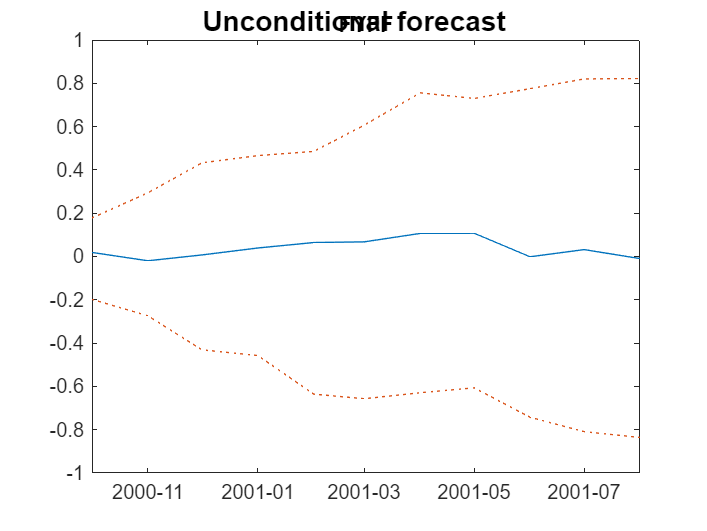


chartpack.forecastPercentiles( ...

    fcastPrctileTbx, modelR1, FigureTitle ="Unconditional forecast")


## Identification

### Cholesky

#### Seting up the identifier

identChol = identifier.Cholesky(order=[]);

modelS1 = Structural(reducedForm=modelR1, identifier=identChol);
modelS1.initialize();


info1 = modelS1.presample(numPresampled);


 Presampling from posterior (MinnesotaFAVAROnestep) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS1.Presampled{1}

ans = struct with fields:
                  beta: [117×1 double]
                 sigma: [3×3 double]
                    FY: [511×3 double]
                    LD: [120×3 double]
    IdentificationDraw: [1×1 struct]
                     D: [3×3 double]


#### Checking transition matrices

modelS1.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {12×1 cell}
        C: {12×1 cell}
    Sigma: [3×3 double]


modelS1.Presampled{1}.IdentificationDraw.A{1,1}

ans =     0.8345    0.3751    0.0064
    0.0875    0.5086    0.0025
    0.0714    0.1046    1.1478
    0.0695    0.0455    0.0108
   -0.0187    0.0359   -0.0052
   -0.1188   -0.1602   -0.1527
    0.0143   -0.0000   -0.0050
    0.0041   -0.0080    0.0051
    0.0167   -0.1248   -0.0360
   -0.0144    0.0144   -0.0020


modelS1.Presampled{1}.IdentificationDraw.A{2,1}

ans =     0.8345    0.3751    0.0064
    0.0875    0.5086    0.0025
    0.0714    0.1046    1.1478
    0.0695    0.0455    0.0108
   -0.0187    0.0359   -0.0052
   -0.1188   -0.1602   -0.1527
    0.0143   -0.0000   -0.0050
    0.0041   -0.0080    0.0051
    0.0167   -0.1248   -0.0360
   -0.0144    0.0144   -0.0020


#### Checking scaling matrix

modelS1.Presampled{1}.D

ans =     0.5367         0         0
         0    0.7905         0
         0         0    0.1661


modelS1.Presampled{2}.D

ans =     0.5254         0         0
         0    0.8333         0
         0         0    0.1661


## Impulse respones (IRF)

### Cholesky

respTbl1 = modelS1.simulateResponses();
respTbl1 = tablex.apply(respTbl1, prctileFunc);


  (MinnesotaFAVAROnestep) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



respTbl1 = tablex.flatten(respTbl1);

respTbl1


respTbl1 = 25×9 timetable
     Time      main_Factor1___main_Factor1_shock    main_Factor1___main_Factor2_shock          main_Factor1___FYFF_shock           main_Factor2___main_Factor1_shock    main_Factor2___main_Factor2_shock       main_Factor2___FYFF_shock              FYFF___main_Factor1_shock                FYFF___main_Factor2_shock                FYFF___FYFF_shock      
    _______    _________________________________    _________________________________    ______________________________________    _________________________________    _________________________________    ________________________________    _____________________________________    _________________________

chartpack.responsePercentiles( ...
    respTbl1, modelS1 ...
    , "figureTitle", "Shock responses (percentiles)" ...
);

## **Historical shock decomposition**

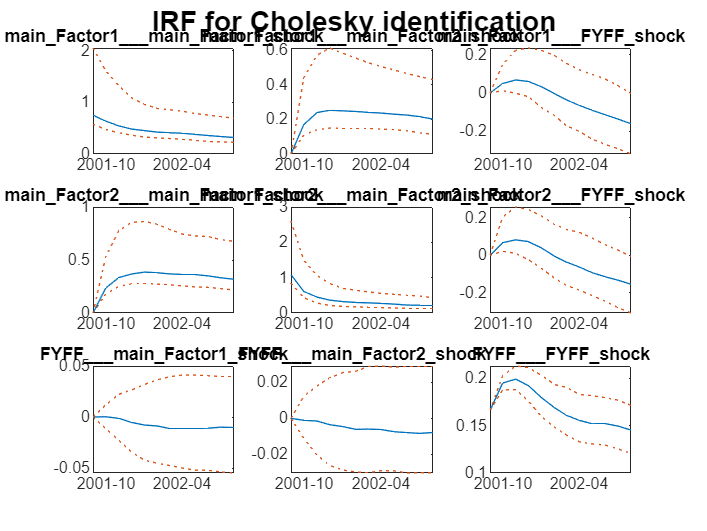

histContTbx = modelS1.calculateContributions();


tablex.getHigherDims(histContTbx)

histContMedTbx = tablex.apply(histContTbx, medianFunc);

chartpack.contributionsMedian( ...
    histContMedTbx, modelS1 ...
    , "figureTitle", "Shock contributions with Cholesky (median)" ...
);

## **Unconditional forecast shock decomposition**

ans = 1×1 cell array
    {["main_Factor1_shock"    "main_Factor2_shock"    "FYFF_shock"    "Exogenous"    "Initials"]}


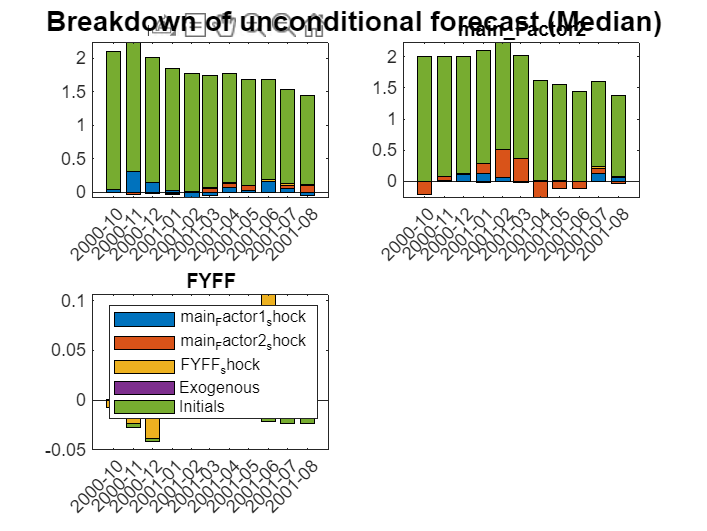


[uncFcastTbl1, uncFcastContribTbl1] = modelS1.forecast( ...

    fcastSpan, ...
    contributions=true ...
);

tablex.getHigherDims(uncFcastContribTbl1)

contMedTbx = tablex.apply(uncFcastContribTbl1, medianFunc);

chartpack.contributionsMedian( ...
    contMedTbx, modelS1 ...
    , "figureTitle", "Unconditional forecast Shock contributions (median)" ...
);


## **FEVD**


  (MinnesotaFAVAROnestep) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



ans = 1×1 cell array
    {["main_Factor1_shock"    "main_Factor2_shock"    "FYFF_shock"]}


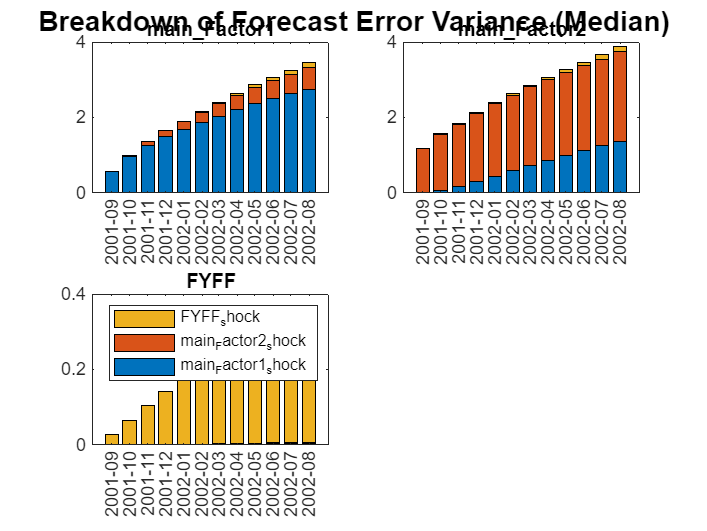

fevdTbx = modelS1.calculateFEVD();

tablex.getHigherDims(fevdTbx)

fevdMedTbx = tablex.apply(fevdTbx, medianFunc);

chartpack.contributionsMedian( ...
    fevdMedTbx, modelS1 ...
    , "figureTitle", "FEVD (median)" ...
);



## Conditional forecast

### Settig up the conditions and the forecast plan

condDataTbl = tablex.fromFile("condDataTblFAVAR.xlsx");
planTbl = tablex.readConditioningPlan("planTblFAVAR.xlsx");


 Conditional forecast [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



### Settig up the forecast range 

cfcastSpan = fcastSpan;

### Running conditional forecast with no simulation plan

[condFcastTbl1, condFcastContribTbl1] = modelS1.conditionalForecast( ...
    cfcastSpan, ...
    conditions=condDataTbl, ...
    plan=[], ...
    exogenousFrom = "conditions" ...
);


 Conditional forecast [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 





condFcastPrctilesTbl1 = tablex.apply(condFcastTbl1, prctileFunc);

### Running conditional forecast with simulation plan

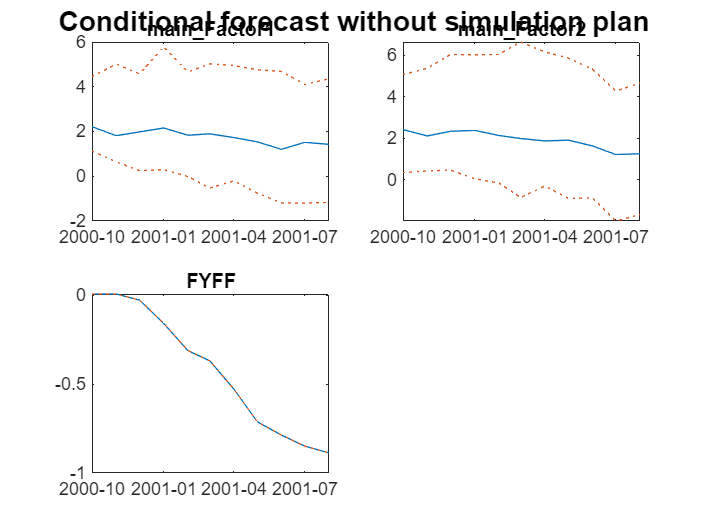

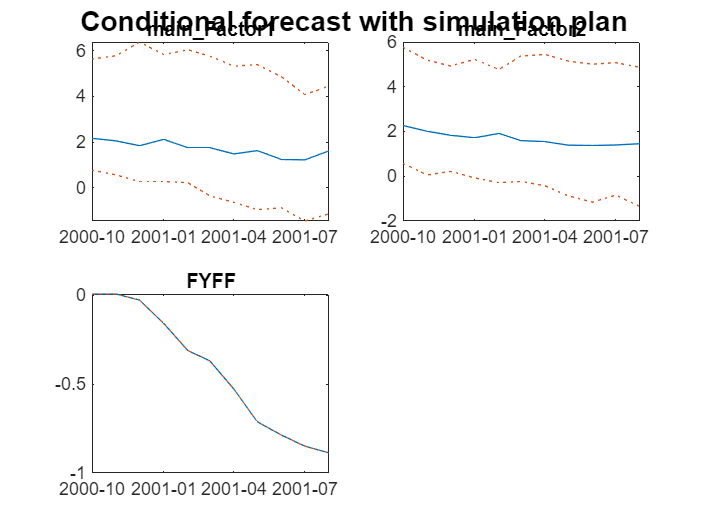

[condFcastTbl2, condFcastContribTbl2] = modelS1.conditionalForecast( ...

    cfcastSpan, ...
    conditions=condDataTbl, ...
    plan=planTbl, ...
    exogenousFrom = "conditions" ...
);


condFcastPrctilesTbl2 = tablex.apply(condFcastTbl2, prctileFunc);

### Visualize the conditional forecast

chartpack.conditionalForecastPercentiles( ...
    condFcastPrctilesTbl1, modelS1 ...
    , "figureTitle", "Conditional forecast w/o plan (percentiles)" ...
);

chartpack.conditionalForecastPercentiles( ...
    condFcastPrctilesTbl2, modelS1 ...
    , "figureTitle", "Conditional forecast with plan (percentiles)" ...
);